# 1. Nonlinear iteration test - MATLAB

Run nonlinear_iteration_test.ipynb first, then Run All here, then compare_results.ipynb. This Live Script and the readable .m use the same code. Raw inputs only: MATLAB independently builds the grid, maps and initial states. The solver calculation below is copied from KLJCmainsv22.m, not rewritten. Test adapters: in-memory Gaussian maps, two source syntax fixes, serial for, history snapshots, and omission of GUI/power-reporting lines 535-600. Cavity tracking fields remain zero as in the original source.

test_directory=fileparts(mfilename('fullpath'));
if ~isfile(fullfile(test_directory,'nonlinear_iteration_test.m'))
    test_directory=fileparts(matlab.desktop.editor.getActiveFilename);
    if ~isfile(fullfile(test_directory,'nonlinear_iteration_test.m'))
        test_directory=fileparts(which('nonlinear_iteration_test.m'));
    end
end
input_file=fullfile(test_directory,'inputs.mat');
assert(isfile(input_file),'Run nonlinear_iteration_test.ipynb first. Missing: %s',input_file);
load(input_file);
assert(N==200 && Nr==1 && mono==1 && all(Ut==Ut(1)));
assert(all(Lsb==pi) && all(ismember(type,[-1,0,1])) && all(nh>=1 & nh<=Ns));

## 2. Gaussian maps - KlyC_v6.mlapp, same copied branch as test 5

Only TXT saving is replaced by in-memory z_mm/e_z arrays.

app=struct();
app.BeamVolEF.Value=Ut(1);
app.Switch_2.Value='GS';
app.UITable_2.Data=zeros(Nc,1);
z_mm=zeros(N+1,Nc);
e_z=zeros(N+1,Nc);
                U0=app.BeamVolEF.Value; % kV
                c=299792458;  % m/s, light speed
                eta0=4E-7*pi*c; % ohm, wave impendance of TEM
                etom=1.7588E11;  % C/kg, charge to mass of electron
                s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
                k0=2*pi*f0*1E9/c; % 1/m
                w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant

                S1=regexp(cavityname,'\s+','split');


                zminarray=zeros(1,Nc);
                zmaxarray=zeros(1,Nc);
                EMflag=0; % to determine whether all the EM solvers are successfully done
                Emax=zeros(1,Nc); % kV/mm, store the maximum electric field with stored energy of 1J
                kais=zeros(4,Nc);% to store the normalized self-calculated kai elements for each cavity
                rcEMs=rc*ones(2,Nc); % mm,to store the beam aperture at the left side and right side of each cavity


                if strcmp(app.Switch_2.Value,'GS')==1  % Guassian profile will be adopted
                    N=200*ones(1,Nc); % number of points,, for Guassian and uniform
                    for kk=1:Nc
                        if M(kk)>0 % To forbid the collapse by non-positive number
                            k=0.5*w0(kk)/s/c/sqrt(-log(M(kk))); % 1/m
                            ezm=(RtoQ(kk)/eta0/pi*k0(kk)*k*k)^0.5*(1000)^(-3/2); % mm^(-3/2)
                            z=[-1/k*3:2*1/k*3/N(kk):1/k*3]'*1000; %mm
                            zminarray(kk)=-1/k*3*1000+zshift(kk);
                            zmaxarray(kk)=1/k*3*1000+zshift(kk);
                            ez=ezm*exp(-k*1E-3*k*1E-3*z.*z); % mm^(-3/2)
                            ezr=repmat(ez,1,Nr);
                            cavity=[z ezr*sign(Qext(kk))];
                            % TEST ONLY: retain maps in memory instead of saving TXT.
                            z_mm(:,kk)=cavity(:,1);
                            e_z(:,kk)=cavity(:,2);
                            Emax(kk)=abs(app.UITable_2.Data(kk,1));
                            if nh(kk)>0
                                EMflag=EMflag+1;
                            end
                        end
                    end
                end

## 3. Initialization - original KLJCmainsv22.m lines 45-209

CALCULATE THE REFERENCE PAMAMETER

Nt = double(Nt)

Nt = 64


Iz0=1/2/pi*2*pi/Nt*sum(Izt(Y0)); % A, araverge emission current
I0=abs(Iz0);
U0=1/2/pi*2*pi/Nt*sum(Izt(Y0).*Ut(Y0))/Iz0;% kV, average emission voltage

% constant
c=299792458;  % m/s, light speed
etom=-1.7588E11;  % C/kg, charge to mass of electron
eta0=4E-7*pi*c; % ohm, wave impendance of TEM

esign=sign(-etom); % for negative charged paticles, esign=1; for postive charged particles, esign=-1
etom=abs(etom);

etom = double(etom);
c    = double(c);
U0   = double(U0);

s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
vetoc=(1-(1+etom/c/c*Ut*1E3).^(-2)).^(1/2); % vet/c
vn1=0*vetoc;
vn1(Y0)=s./vetoc(Y0); % ve0/ve(t) at the entrance


w=2*pi*f*1E9;  % rad/s, angular frequency of operating
w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant
k0=w0/c/1000;   % 1/mm,  wave number at resonant freqency
Lsb=pi*ones(1,Nc); % phaseshift beta0*Ls from the entrance of output cavity at resonant freqency

gama=1+etom*U0*1000/c/c; % Lorentz factor
betae=w/c/s/1000;  % 1/mm, betae at operating freqency

Nz = double(Nz);
dz=2*pi/betae/Nz;  % mm,

dz=L/floor(L/dz); % mm, increment of z
dz = double(dz);
zi=(z0:dz:z0+L)'; % mm, z position sequence

rcvs=interp1(rcv(1,:),rcv(2,:)*rc,zi,'linear','extrap'); % mm, tunnel radius sequence

if rc~=0  % for cylindrical beam
    dN=floor(factorregion*rc/2.40483/dz); % N dz interval is included to calculate the local SP
    Nesz=zeros(length(zi),2); % TEST: remove original stray N
    for k=1:length(zi)
        Nesz(k,1)=max(1,k-dN); % min order of interval
        Nesz(k,2)=min(length(zi),k+dN); % max order of interval
    end
else  % for sheet beam

end
assert(~(dN==1 && factor~=0 && fillfactor~=0 && DCSPfactor~=0), 'Original prefill requires dN different from 1.');


ez=zeros(length(zi),Nc); % mm^(-3/2),normalized electric field stored or coupling impedance /ohm
C3=ez*0;
vpz=ez*0;
alfaz=ez*0;
S=regexp(cavityname,'\s+','split');


for k=1:Nc % For every cavity
    if nh(k)>Ns % If the cavity 
        continue;
    end
    A=[z_mm(:,k),e_z(:,k)]; % TEST: generated map instead of TXT load
    A(:,1)=A(:,1)+zshift(k);
    if min(A(:,1))<=z0+dz/10 || max(A(:,1))>=z0+L-dz/10
        fprintf('warning: the emission plate is located in the field margin of ');
        fprintf('cavity number ');fprintf(num2str(k));fprintf('\n');
    end
    
    if type(k)~=2
        AA=[A(1,1)-2*dz/10,0;A(1,1)-dz/10,0;A;A(length(A(:,1)),1)+dz/10,0;A(length(A(:,1)),1)+2*dz/10,0];
        ez(:,k)=interp1(AA(:,1),AA(:,2),zi,'linear','extrap'); % mm^(-3/2), normalized e-field sequence; or kV/mm, DC e-field
        if nh(k)==0
            C3(:,k)=(ez(:,k)/betae/U0);    % for normalized DC E-field
        else
            C3(:,k)=(ez(:,k)*eta0*I0/k0(k)^(1/2)/betae/U0/1000);
        end
    else

    end
end


z=betae*zi; % normalized z position
dt=betae*dz; % normalized time step & normalized position step, in real time step=position step/injecting velocity of electron


Iz=zeros(length(z),Ns);
QQ=zeros(length(z),Ns);

% intial value given
Y=Y0;
IzDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0)*ones(length(z),1); % normalized DC current along the axis
for k=1:Ns
    Iz(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)))*ones(length(z),1); % normalized,intial modulated current of 1st harmonic
end

QQDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*vn1(Y))*ones(length(z),1); % DC charge density along axis
for k=1:Ns
    QQ(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)).*vn1(Y))*ones(length(z),1); % normalized,intial modulated charged density
end

if rc~=0
    wp=factor*sqrt(I0*etom/pi/((rm2*1E-3)^2-(rm1*1E-3)^2)/(1/c/eta0)/c/s); % rad/s, plasma angular frquency
else
    
end

effe=0*ones(length(z),1); % if all electron reflected, the efficiency will be 100%
vez=1*ones(length(z),1); % ve/ve0
gamaz=(1-(vez*s).^2).^(-1/2);

% Now we compute a prefill space charge
Esz00=zeros(length(z),1+Ns);

if factor~=0 && fillfactor~=0 && DCSPfactor~=0
    % For DC beam filled ahead of the entrance
    zp=repmat([z(1)-betae*dz:-betae*dz:z(1)-betae*dz*dN].',1,Ns+1);
    [Nfill,~]=size(zp);
    gamazp=[ones(Nfill,1),repmat(gamaz(1),Nfill,Ns)];
    QQfill=[repmat(QQDC(1),Nfill,1) repmat(QQ(1,:),Nfill,1).*exp(-1i*repmat([1:Ns],Nfill,1).*(z(1)-zp(:,2:end)))];
    if rc~=0  % for cylindrical beam
        for kk=1:length(z)
            Esz00(kk,:)=esign*dz*betae*sum(-QQfill.*sign(z(kk)-zp)/2*wp^2/w^2*(gama+1)/gama/gama.*(exp(-2.40483*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/2.40483*(rm2*besselj(1,2.40483*rm2/rc)-rm1*besselj(1,2.40483*rm1/rc))/besselj(1,2.40483))^2+exp(-5.52008*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/5.52008*(rm2*besselj(1,5.52008*rm2/rc)-rm1*besselj(1,5.52008*rm1/rc))/besselj(1,5.52008))^2+exp(-8.65373*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/8.65373*(rm2*besselj(1,8.65373*rm2/rc)-rm1*besselj(1,8.65373*rm1/rc))/besselj(1,8.65373))^2+exp(-11.79153*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/11.79153*(rm2*besselj(1,11.79153*rm2/rc)-rm1*besselj(1,11.79153*rm1/rc))/besselj(1,11.79153))^2+exp(-14.93092*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/14.93092*(rm2*besselj(1,14.93092*rm2/rc)-rm1*besselj(1,14.93092*rm1/rc))/besselj(1,14.93092))^2));
        end
        
    else   % for sheet beam

    end
    
end

flagVnc=zeros(1,Nc);  % record the mode voltage
effendflag=0;
Pinflag=sign(Pin); % if Pin is negative, BW analysis will be adopted in TW analysis
Pin=abs(Pin); % W, Pin itself should be a positive number
Vin=(Pin/U0/1000/Nbeam/I0).^0.5.*(2*Nbeam*I0/U0/1000*eta0).^0.5;% normalized mode voltage of TE10

% Precomputing the terms of alpha (eq. 85) this time not at the input, but
% in the whole tube (rcvs, the tube radius is a function of z)
if rc~=0  % for cylindrical beam
    Eszr1=(2/2.40483*(rm2*besselj(1,2.40483*rm2./rcvs)-rm1*besselj(1,2.40483*rm1./rcvs))/besselj(1,2.40483)).^2;
    Eszr2=(2/5.52008*(rm2*besselj(1,5.52008*rm2./rcvs)-rm1*besselj(1,5.52008*rm1./rcvs))/besselj(1,5.52008)).^2;
    Eszr3=(2/8.65373*(rm2*besselj(1,8.65373*rm2./rcvs)-rm1*besselj(1,8.65373*rm1./rcvs))/besselj(1,8.65373)).^2;
    Eszr4=(2/11.79153*(rm2*besselj(1,11.79153*rm2./rcvs)-rm1*besselj(1,11.79153*rm1./rcvs))/besselj(1,11.79153)).^2;
    Eszr5=(2/14.93092*(rm2*besselj(1,14.93092*rm2./rcvs)-rm1*besselj(1,14.93092*rm1./rcvs))/besselj(1,14.93092)).^2;
end

SCmethod=0; % local space charge method will be adopted intially to speed up the calculation
iterationsuc=0; % 0--failed to convergence; 1--succeed to convergence

nnp=0; % for power ramping method
pinNpin=zeros(Npin,1); % store the input power in stair case
effNpin=zeros(Npin,1); % store the balanced efficiency for ramping method
phsNpin=zeros(Npin,1); % store phs/2/pi for ramping method

kai=kai*mono; % coupling analysis is not supported in monotron oscillation
wsp=w; % Hz, to store angular frequency shifting while doing iterations of monotron oscillation
Vnce=0; % To store the normalized mode voltage evoluation over the iteration of monotron oscillation

## 4. Nonlinear loop - original lines 210-534 and 601-626

Histories record evaluated passes before the control decisions. SCmethods identifies the method USED, not the next method after a switch.

iterations=[]; Vnc_history=[]; Vnp_history=[]; SCmethods=[]; drivefactors=[];
effend_history=[]; residential_history=[]; residentialel_history=[];
skipped_iterations=[];
iterf=sign(iterfactor); % space charge modification or not
iterfactor=abs(iterfactor);
for nn=1:Nlimit
    
    if nn>1 && abs(moviedisp(4))==2 && residential<Rlimit  && min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)==min(1/Npin*(floor(2*(nn-1)/Nlimit*Npin)+1),1)
        skipped_iterations(end+1)=nn; % TEST: record skipped ramp index
        continue; % skip the current loop in the ramping mode
    end
    SCmethods(end+1)=SCmethod; % TEST: method used by this pass
    drivefactors(end+1)=max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)));
    
    % mode E-field calcuated
    Vnp=zeros(1,Nc); % normalized waveguide voltage * sqrt(eta0/z0)
    Vnc=zeros(1,Nc);
    
    
    Mc=zeros(2*Nc,2*Nc);
    B=zeros(2*Nc,1);
    
    for k=1:Nc
        
        if type(k)==-1 && nh(k)<=Ns % FOR OUTPUT CAVITY
            B((2*k-1):(2*k))=[0;-esign*Nbeam*trapz(z,C3(:,k).*Iz(:,nh(k)))];
            Mc(2*k-1,2*k-1)=sqrt(Qext(k))*(gaman(k)*exp(1i*Lsb(k))+exp(-1i*Lsb(k)));
            Mc(2*k,2*k-1)=sqrt(1/Qext(k))*(gaman(k)*exp(1i*Lsb(k))-exp(-1i*Lsb(k)));
            Mc(2*k-1,2*k)=-1;
            if mono==0 && nn>1
                dfmono=imag(B(2*k))/real(B(2*k))*(-1/Qin(k)+real(Mc(2*k,2*k-1)/Mc(2*k-1,2*k-1)))-imag(Mc(2*k,2*k-1)/Mc(2*k-1,2*k-1)); % To make sure Vnc is positive number
                ws=(dfmono/(-2)*w0(k)+w0(k))/nh(k);
                wsp=[wsp,ws];
                % disp(ws/2/pi*1E-9);
                
                Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*ws-w0(k))/w0(k)+1i*2*kai(k,k));
            else
                Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*w-w0(k))/w0(k)+1i*2*kai(k,k));
            end
            if k<Nc
                Mc(2*k,2*(k+1):2:2*Nc)=-1i*kai(k,(k+1):Nc);
            end
            if k>1
                Mc(2*k,2:2:2*(k-1))=-1i*kai(k,1:(k-1));
            end
            
            
        elseif type(k)==0  && nh(k)<=Ns % FOR INPUT CAVITY
            Mc(2*k-1,2*k-1)=sqrt(Qext(k))*exp(-1i*Lsb(k));
            Mc(2*k,2*k-1)=sqrt(1/Qext(k))*(-exp(-1i*Lsb(k)));
            Mc(2*k-1,2*k)=-1;
            Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*w-w0(k))/w0(k)+1i*2*kai(k,k));
            if k<Nc
                Mc(2*k,2*(k+1):2:2*Nc)=-1i*kai(k,(k+1):Nc);
            end
            if k>1
                Mc(2*k,2:2:2*(k-1))=-1i*kai(k,1:(k-1));
            end
            B((2*k-1):(2*k))=[-sqrt(Qext(k))*exp(1i*Lsb(k))*Vin(k)*max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)));-esign*Nbeam*trapz(z,C3(:,k).*Iz(:,nh(k)))-sqrt(1/Qext(k))*exp(1i*Lsb(k))*Vin(k)*max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)))];
            
        elseif type(k)==1 && nh(k)<=Ns && nh(k)>=1 % FOR BUNCH CAVITY
            Mc(2*k-1,2*k-1)=1;
            Mc(2*k,2*k-1)=0;
            Mc(2*k-1,2*k)=0;
            Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*w-w0(k))/w0(k)+1i*2*kai(k,k));
            if k<Nc
                Mc(2*k,2*(k+1):2:2*Nc)=-1i*kai(k,(k+1):Nc);
            end
            if k>1
                Mc(2*k,2:2:2*(k-1))=-1i*kai(k,1:(k-1));
            end
            B((2*k-1):(2*k))=[0;-esign*Nbeam*trapz(z,C3(:,k).*Iz(:,nh(k)))]; % n-harmonic current stimulation
            
            
        else
            Mc(2*k-1,2*k-1)=1;
            Mc(2*k,2*k-1)=0;
            Mc(2*k-1,2*k)=0;
            Mc(2*k,2*k)=1;
            B((2*k-1):(2*k))=[0;0];
        end
        
    end
    
    
    temp=Mc\B;
    Vnp=temp(1:2:(2*Nc)).'; % normalized voltage for output microwave
    Vnc=temp(2:2:(2*Nc)).'; % normalized voltage for cavity mode
    
    if mono==0 && nn==1% monotron oscillation analysis activated
        Vnc=0.1; % intial value should be small real number
        Vnce=Vnc;
    elseif mono==0 && nn>1
        Vnce=[Vnce Vnc];
    else
        % do nothing for normal Klystron simulations
    end
    
    
    
    Emz=zeros(length(z),Ns); % normlized mode E-field distribution,1st to Ns
    Emz0=zeros(length(z),1); % normlized mode E-field distribution for DC gap
    Pmz=Emz; % to save traveling wave power flow normalized by U0*I0
    Pmzloss=zeros(1,Nc); % to save accumulative TW ohmmic loss normalized by U0*I0
    Emzinh=0; % normalized Emz field for the inherentation
    kkinh=0; % which z index number for the start of inherentation
    
    
    
    
    % space charge field calculated
    Esz=zeros(length(z),Ns);
    Esz0=zeros(length(z),1);
    Esztotal=[Esz0,Esz];
    QQtotal=[QQDC,QQ];
    if nn~=1 && factor~=0 && SCmethod~=0
        if rc~=0  % for cylindrical beam
            for kk=1:length(z) % par for
                Esztotal(kk,:)=esign*dz*betae*sum(-QQtotal(Nesz(kk,1):Nesz(kk,2),:).*[sign(z(kk)-z(Nesz(kk,1):Nesz(kk,2)))/2*wp^2/w^2*(gama+1)/gama/gama ...
                    .*(exp(-2.40483*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr1(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-5.52008*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr2(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-8.65373*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr3(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-11.79153*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr4(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-14.93092*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr5(Nesz(kk,1):Nesz(kk,2)))...
                    ,repmat(sign(z(kk)-z(Nesz(kk,1):Nesz(kk,2)))/2*wp^2/w^2*(gama+1)/gama/gama.*(exp(-2.40483*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr1(Nesz(kk,1):Nesz(kk,2))+exp(-5.52008*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr2(Nesz(kk,1):Nesz(kk,2))+exp(-8.65373*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr3(Nesz(kk,1):Nesz(kk,2))+exp(-11.79153*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr4(Nesz(kk,1):Nesz(kk,2))+exp(-14.93092*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr5(Nesz(kk,1):Nesz(kk,2))),1,Ns)]);
            end
            
        else

        end
        Esz=Esztotal(:,2:(Ns+1))+fillfactor*Esz00(:,2:(Ns+1));
        Esz0=DCSPfactor*(Esztotal(:,1)+fillfactor*Esz00(:,1));
    elseif nn~=1 && factor~=0 && SCmethod==0
        if rc~=0  % for cylindrical beam
            for k=1:Ns
                Esz(:,k)=-esign*1i*Iz(:,k)/k*wp^2/w^2*(gama+1)/gama/gama*1/(rm2^2-rm1^2).*(Eszr1./(1+(2.40483/k/rc/betae*vez.*gamaz).^2)+Eszr2./(1+(5.52008/k/rc/betae*vez.*gamaz).^2)+Eszr3./(1+(8.65373/k/rc/betae*vez.*gamaz).^2)+Eszr4./(1+(11.79153/k/rc/betae*vez.*gamaz).^2)+Eszr5./(1+(14.93092/k/rc/betae*vez.*gamaz).^2));
            end
        else

        end
    else
        % do nothing
        
    end
    
    Esmz=Esz+Emz; % normalized RF electric field
    Esz0_space_charge=Esz0; % TEST: preserve separate SC DC contribution
    Esz0=Esz0+Emz0; % normalized DC electric field
    
    
    Zn=1./zeros(Ntimes*length(z),length(t0)); % Storage of the normalized arriving position
    Vn=1./zeros(Ntimes*length(z),length(t0)); % Storage of the normlalized velocity ve/ve0
    Tn=zeros(Ntimes*length(z),length(t0)); % storage of the normalized evolution time
    
    % initial value
    Zn(1,:)=z(1)*ones(1,Nt); % z
    Vn(1,:)=1./vn1; % ve/ve0
    Tn(1,:)=tn1;
    
    Tnz=zeros(length(z),length(t0)); % Storage of the normalized arriving time
    Vnz=zeros(length(z),length(t0)); % Storage of the normlalized reciprocal number of velocity
    % initial value
    Tnz(1,:)=tn1;
    Vnz(1,:)=vn1;
    
    % calculate the electron movement
    Y=Y0; % record the number activated electron
    Yflag=0; % detect whether there is reflected electrons
    Utn=0*Ut; %kV, to store the beam voltage at the exit
    ttn=0*t0; % normalized arrival time at exit
    % calculate the trajectories for each single electron and update the
    % current and charge information
    
    Pe=zeros(length(z),1); % average beam voltage/511kV*2*pi
    % reset for the updated parameters
    IzDCr=0*IzDC;
    Izr=0*Iz;
    QQDCr=0*QQDC;
    QQr=0*QQ;
    
    % beam dynamic computation
    kz=1;
    IzDCr(kz)=1/2/pi*sum((2*pi/Nt)*(Izt(Y0)/Iz0));
    for kk=1:Ns
        Izr(kz,kk)=1i/pi*sum((2*pi/Nt)*(Izt(Y0)/Iz0.*exp(-kk*1i*tn1(Y0)))); % normalized,modulated current depth of kkth harmonic
    end
    QQDCr(kz)=1/2/pi*sum((2*pi/Nt)*(Izt(Y0)/Iz0.*vn1(Y0))); % DC charge density along axis
    %     for kk=1:Ns
    %         QQr(kz,kk)=1i/pi*(2*pi/Nt)*sum((Izt(Y0)/Iz0.*exp(-kk*1i*tn1(Y0)).*vn1(Y0))); % normalized,intial modulated charged density
    %     end
    Pe(kz)=sum((2*pi/Nt)*(Izt(Y0)/Iz0).*((1-(s./vn1(Y0)).^2).^(-1/2)-1));
    
    for kz=1:(length(z)-1)
        Tnz(kz+1,Y)=Tnz(kz,Y)+(z(kz+1)-z(kz))*Vnz(kz,Y);
        Est=0*t0;
        if nn>5 && abs(Iz(kz,1))>0.01 && iterf<=0
            Esmz(kz,:)=Esz(kz,:).*Izr(kz,:)./Iz(kz,:)+Emz(kz,:);
        end
        for kk=1:Ns
            Est(Y)=Est(Y)+imag(Esmz(kz,kk).*exp(kk*1i*Tnz(kz,Y)));
        end
        Est(Y)=Est(Y)+Esz0(kz);
        Vnz(kz+1,Y)=Vnz(kz,Y)+esign*(z(kz+1)-z(kz))*1/s^2*(1/sqrt(1-s^2)-1)*(1-s^2./Vnz(kz,Y)./Vnz(kz,Y)).^(3/2).*Vnz(kz,Y).*Vnz(kz,Y).*Vnz(kz,Y).*Est(Y);
        
        Zn(kz+1,Y)=z(kz+1);
        Vn(kz+1,Y)=1./Vnz(kz+1,Y);
        Tn(kz+1,Y)=Tnz(kz+1,Y);
        IzDCr(kz+1)=1/2/pi*sum((2*pi/Nt)*(Izt(Y0)/Iz0));
        for kk=1:Ns
            Izr(kz+1,kk)=1i/pi*sum((2*pi/Nt)*(Izt(Y0)/Iz0.*exp(-kk*1i*Tnz(kz+1,Y0)))); % normalized,modulated current depth of kkth harmonic
        end
        QQDCr(kz+1)=1/2/pi*sum((2*pi/Nt)*(Izt(Y0)/Iz0.*Vnz(kz+1,Y0))); % DC charge density along axis
        %         for kk=1:Ns
        %             QQr(kz+1,kk)=1i/pi*(2*pi/Nt)*sum((Izt(Y0)/Iz0.*exp(-kk*1i*Tnz(kz+1,Y0)).*Vnz(kz+1,Y0))); % normalized,intial modulated charged density
        %         end
        Pe(kz+1)=sum((2*pi/Nt)*(Izt(Y0)/Iz0).*((1-(s./Vnz(kz+1,Y0)).^2).^(-1/2)-1));
        
        if max((Vnz(kz+1,Y)-Vnz(kz,Y))./Vnz(kz,Y))>evolutionmethod(1)
            %       disp(kz);
            break;
        end
    end
    
    if kz==length(z)-1
        %    end of all electrons by parallel computation
        Tn((length(z)+1):Ntimes*length(z),Y)=repmat(Tn(length(z),Y),(Ntimes-1)*length(z),1)+repmat([dt:dt:((Ntimes-1)*length(z)*dt)]',1,length(Y));
        Utn(Y)=1E-3*c*c/etom*((1-(s./Vnz(length(z),Y)).^2).^(-1/2)-1); % kV,electron beam voltage at the exit
        ttn(Y)=Tnz(length(z),Y); % normalized arrival time at exit
        Yflag=length(Y); % all electrons exits
    else
        Tn((kz+1):Ntimes*length(z),Y)=repmat(Tn(kz+1,Y),Ntimes*length(z)-kz,1)+repmat([0:dt:((Ntimes*length(z)-kz)*dt-dt)]',1,length(Y)); % storage of the normalized evolution time
        kzstart=kz+1;
        for kt=Y0
            kz=kzstart;
            kzrest=0;
            for k=kzstart:(Ntimes*length(z)-1)
                kzp=kz; % stored previous serial number
                if k~=kzstart
                    kz=1+floor((Zn(k,kt)-z(1))/dt);
                    kzrest=(Zn(k,kt)-z(1))/dt-floor((Zn(k,kt)-z(1))/dt);
                end
                tt=Tn(k,kt); % normalized time points
                % judge the end condition for one electron
                if kz<=0
                    kz=0;
                    Tnz(kzp:-1:kz+1,kt)=tt-dt+(z(kzp:-1:kz+1)-Zn(k-1,kt))/Vn(k-1,kt);
                    Vnz(kzp:-1:kz+1,kt)=1/Vn(k-1,kt);
                    IzDCr(kzp:-1:kz+1)=IzDCr(kzp:-1:kz+1)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt));
                    Izr(kzp:-1:kz+1,:)=Izr(kzp:-1:kz+1,:)+1i/pi*(2*pi/Nt)*(Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp:-1:kz+1),1)*1i.*repmat((tt-dt+(z(kzp:-1:kz+1)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns)))*sign(Vn(k-1,kt)); % normalized,modulated current depth of kkth harmonic
                    QQDCr(kzp:-1:kz+1)=QQDCr(kzp:-1:kz+1)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0/abs(Vn(k-1,kt))); % DC charge density along axis
                    %               QQr(kzp:-1:kz+1,:)=QQr(kzp:-1:kz+1,:)+1i/pi*(2*pi/Nt)*(Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp:-1:kz+1),1)*1i.*repmat((tt-dt+(z(kzp:-1:kz+1)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns))/abs(Vn(k-1,kt))); % normalized,intial modulated charged density
                    Pe(kzp:-1:kz+1)=Pe(kzp:-1:kz+1)+(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt))*((1-(s*Vn(k-1,kt))^2)^(-1/2)-1);
                    break;
                elseif kz>=length(z)+1
                    if kzp+1<=length(z)
                        kz=length(z);
                        Tnz(kzp+1:1:kz,kt)=tt-dt+(z(kzp+1:1:kz)-Zn(k-1,kt))/Vn(k-1,kt);
                        Vnz(kzp+1:1:kz,kt)=1/Vn(k-1,kt);
                        IzDCr(kzp+1:1:kz)=IzDCr(kzp+1:1:kz)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt));
                        Izr(kzp+1:1:kz,:)=Izr(kzp+1:1:kz,:)+1i/pi*(2*pi/Nt)*(Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp+1:1:kz),1)*1i.*repmat((tt-dt+(z(kzp+1:1:kz)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns)))*sign(Vn(k-1,kt)); % normalized,modulated current depth of kkth harmonic
                        QQDCr(kzp+1:1:kz)=QQDCr(kzp+1:1:kz)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0/abs(Vn(k-1,kt))); % DC charge density along axis
                        %                   QQr(kzp+1:1:kz,:)=QQr(kzp+1:1:kz,:)+1i/pi*(2*pi/Nt)*(Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp+1:1:kz),1)*1i.*repmat((tt-dt+(z(kzp+1:1:kz)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns))/abs(Vn(k-1,kt))); % normalized,intial modulated charged density
                        Pe(kzp+1:1:kz)=Pe(kzp+1:1:kz)+(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt))*((1-(s*Vn(k-1,kt))^2)^(-1/2)-1);
                    end
                    Yflag=Yflag+1;
                    Utn(kt)=1E-3*c*c/etom*((1-(s*Vn(k-1,kt)).^2).^(-1/2)-1); % kV,electron beam voltage at the exit
                    ttn(kt)=tt; % normalized arrival time at exit
                    break;
                else
                    % do nothing, contine the movement
                end
                
                Zn(k+1,kt)=Zn(k,kt)+dt*Vn(k,kt);
                if kz==length(z)
                    Est=sum(imag(Esmz(kz,:).*exp([1:1:Ns]*1i*tt)))+Esz0(kz);
                else
                    Est=sum(imag(((1-kzrest)*Esmz(kz,:)+kzrest*Esmz(kz+1,:)).*exp([1:1:Ns]*1i*tt)))+(1-kzrest)*Esz0(kz)+kzrest*Esz0(kz+1);
                end
                Vn(k+1,kt)=Vn(k,kt)-esign*dt*1/s^2*(1/sqrt(1-s^2)-1)*(1-s^2*Vn(k,kt)*Vn(k,kt))^(3/2)*Est;
                
                % update those terms for the calculation of current and density
                % harmonics
                
                if kz>kzp
                    Tnz(kzp+1:1:kz,kt)=tt-dt+(z(kzp+1:1:kz)-Zn(k-1,kt))/Vn(k-1,kt);
                    Vnz(kzp+1:1:kz,kt)=1/Vn(k-1,kt);
                    IzDCr(kzp+1:1:kz)=IzDCr(kzp+1:1:kz)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt));
                    QQDCr(kzp+1:1:kz)=QQDCr(kzp+1:1:kz)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0/abs(Vn(k-1,kt))); % DC charge density along axis
                    Izr(kzp+1:1:kz,:)=Izr(kzp+1:1:kz,:)+1i/pi*(2*pi/Nt)*Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp+1:1:kz),1)*1i.*repmat((tt-dt+(z(kzp+1:1:kz)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns))*sign(Vn(k-1,kt)); % normalized,modulated current depth of kkth harmonic
                    %               QQr(kzp+1:1:kz,:)=QQr(kzp+1:1:kz,:)+1i/pi*(2*pi/Nt)*Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp+1:1:kz),1)*1i.*repmat((tt-dt+(z(kzp+1:1:kz)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns))/abs(Vn(k-1,kt)); % normalized,intial modulated charged density
                    Pe(kzp+1:1:kz)=Pe(kzp+1:1:kz)+(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt))*((1-(s*Vn(k-1,kt))^2)^(-1/2)-1);
                    
                elseif kz<kzp
                    Tnz(kzp:-1:kz+1,kt)=tt-dt+(z(kzp:-1:kz+1)-Zn(k-1,kt))/Vn(k-1,kt);
                    Vnz(kzp:-1:kz+1,kt)=1/Vn(k-1,kt);
                    IzDCr(kzp:-1:kz+1)=IzDCr(kzp:-1:kz+1)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt));
                    QQDCr(kzp:-1:kz+1)=QQDCr(kzp:-1:kz+1)+1/2/pi*(2*pi/Nt)*(Izt(kt)/Iz0/abs(Vn(k-1,kt))); % DC charge density along axis
                    Izr(kzp:-1:kz+1,:)=Izr(kzp:-1:kz+1,:)+1i/pi*(2*pi/Nt)*Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp:-1:kz+1),1)*1i.*repmat((tt-dt+(z(kzp:-1:kz+1)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns))*sign(Vn(k-1,kt)); % normalized,modulated current depth of kkth harmonic
                    %               QQr(kzp:-1:kz+1,:)=QQr(kzp:-1:kz+1,:)+1i/pi*(2*pi/Nt)*Izt(kt)/Iz0*exp(-repmat([1:1:Ns],length(kzp:-1:kz+1),1)*1i.*repmat((tt-dt+(z(kzp:-1:kz+1)-Zn(k-1,kt))/Vn(k-1,kt)),1,Ns))/abs(Vn(k-1,kt)); % normalized,intial modulated charged density
                    Pe(kzp:-1:kz+1)=Pe(kzp:-1:kz+1)+(2*pi/Nt)*(Izt(kt)/Iz0)*sign(Vn(k-1,kt))*((1-(s*Vn(k-1,kt))^2)^(-1/2)-1);
                    if  zi(kz)<min(zi)+GIFpara(4)
                        break; % discard the electron here
                    end
                else
                    % do nothing
                end
                
            end
            %  end of one electron
        end
        %    end of all electrons
        
    end
    if Ns==1
        Fy=gradient(Izr,dt);
    else
        [~,Fy]=gradient(Izr,1,dt);
    end
    QQr=-1/1i./repmat([1:1:Ns],length(z),1).*Fy;
    
    IzDC=(1-iterfactor)*IzDC+iterfactor*IzDCr;
    Iz=(1-iterfactor)*Iz+iterfactor*Izr;
    QQDC=(1-iterfactor)*QQDC+iterfactor*QQDCr;
    QQ=(1-iterfactor)*QQ+iterfactor*QQr;
    
    effe=1-c*c/etom*1E-3*Pe/sum((2*pi/Nt)*Izt(Y0)/Iz0.*Ut(Y0));
    vez=1/s*(1-(1+(1/2/pi*Pe./IzDC)).^(-2)).^(1/2);
    gamaz=(1-(vez*s).^2).^(-1/2);
    
    effend=interp1(zi,effe,max(zi)-GIFpara(5));
    residential=max(abs(flagVnc-Vnc)./abs(Vnc));
    residentialel=abs((effendflag-effend)/effend);
    % TEST: record results; no change to the solver's working states.
    iterations(end+1)=nn;
    Vnc_history(end+1,:)=Vnc;
    Vnp_history(end+1,:)=Vnp;
    effend_history(end+1)=effend;
    residential_history(end+1)=residential;
    residentialel_history(end+1)=residentialel;
    if Yflag~=length(Y) && moviedisp(4)<0 % negative number means simulator is in optimization mode
        break;
    end
    if (residential<Rlimit && SCmethod==1 && max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)))==1) || (residential<evolutionmethod(2) && SCmethod==0 && evolutionmethod(2)<=Rlimit && max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)))==1)
        if moviedisp(5)~=1
            fprintf(' \n');
            %         saveas(gcf,'Convergency curve.jpg');
        end
        fprintf('successful iteration:');
        iterationsuc=1;
        fprintf(' Total Iteration number= ');fprintf(num2str(nn)); fprintf(' ,  ');
        fprintf(' final RF residential= ');fprintf(num2str(residential)); fprintf(' ,  ');
        fprintf(' final El residential= ');fprintf(num2str(residentialel)); fprintf(' \n');
        break;
    elseif residential<evolutionmethod(2) && SCmethod==0 && evolutionmethod(2)>Rlimit
        SCmethod=1;
        flagVnc=zeros(1,Nc); % start the global SC method calculation
        effendflag=0;
    else
        flagVnc=Vnc;
        effendflag=effend;
    end
    
    
    
end

successful iteration:

 Total Iteration number= 16 ,  

 final RF residential= 6.3606e-05 ,  

 final El residential= 0.00026046 


## 5. Export the final solution using unambiguous field names

MATLAB reused Esz0 for the DC sum inside the loop. Export both contributions.

Esmz0=Esz0;
Esz0=Esz0_space_charge;
save(fullfile(test_directory,'matlab_results.mat'), ...
    'run_id','zi','z','U0','I0','s','betae','dt','ez','C3','wp','Esz00', ...
    'Esz','Esz0','Emz','Emz0','Esmz','Esmz0','nn','iterationsuc','SCmethod','effendflag', ...
    'iterations','Vnc_history','Vnp_history','SCmethods','drivefactors','skipped_iterations', ...
    'effend_history','residential_history','residentialel_history', ...
    'Iz','QQ','IzDC','QQDC','effe','vez','gamaz','Mc','B','Vnc','Vnp','Vin','flagVnc', ...
    'Zn','Vn','Tn','Tnz','Vnz','Utn','ttn','Y','Yflag','Pe','Izr','IzDCr','QQr','QQDCr','-v7');
fprintf('Last iteration: %d; evaluated: %d; iterationsuc: %d\n',nn,length(iterations),iterationsuc);

Last iteration: 16; evaluated: 16; iterationsuc: 1


disp('Final Vnc:'); disp(Vnc);

Final Vnc:
  -0.0027 - 1.4085i  -0.1972 - 0.1979i   0.0807 - 0.0398i   0.0467 + 0.0394i   0.0305 + 0.2052i



disp('SC methods used:'); disp(SCmethods);

SC methods used:
     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



## 6. Final fields, current and convergence

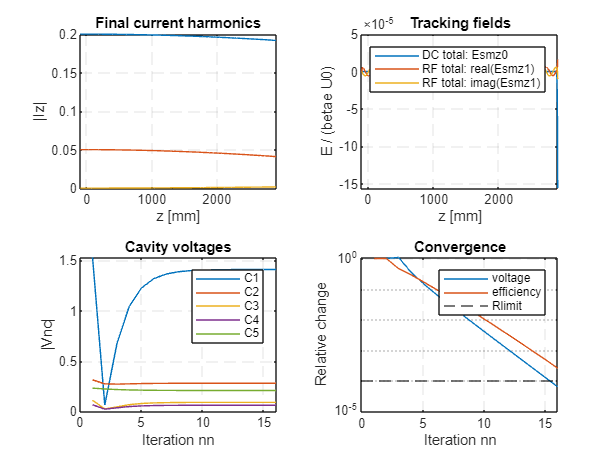

figure;
tiledlayout(2,2);
nexttile; plot(zi,abs(Iz));
xlabel('z [mm]'); ylabel('|Iz|'); title('Final current harmonics');
nexttile; plot(zi,real(Esmz0),zi,real(Esmz(:,1)),zi,imag(Esmz(:,1)));
xlabel('z [mm]'); ylabel('E / (betae U0)'); title('Tracking fields');
legend('DC total: Esmz0','RF total: real(Esmz1)','RF total: imag(Esmz1)');
nexttile; plot(iterations,abs(Vnc_history));
xlabel('Iteration nn'); ylabel('|Vnc|'); title('Cavity voltages'); legend(S);
nexttile; semilogy(iterations,max(residential_history,1e-15),iterations,max(residentialel_history,1e-15));
hold on; yline(Rlimit,'k--');
xlabel('Iteration nn'); ylabel('Relative change'); title('Convergence');
legend('voltage','efficiency','Rlimit');
axes_list=findall(gcf,'Type','axes');
set(axes_list,'XGrid','on','YGrid','on','GridLineStyle','--','GridColor',[.5 .5 .5]);

disp('Saved matlab_results.mat. Next run compare_results.ipynb.');

Saved matlab_results.mat. Next run compare_results.ipynb.
